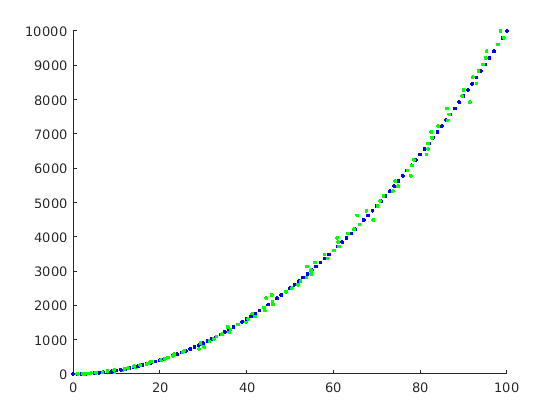

clearvars

car = UGV(0,0);
drone = UAV(1,1,1,1);

x = (0:1:100);
y = x.^2;

figure
hold on
for i=1:length(x)
    car = car.move(x(i), y(i));
    plot(car.x, car.y, 'b.');
    
    drone.cam = drone.cam.update(car.x, car.y);     % fictitious
%     [tmpx, tmpy] = drone.cam.getPos();
%     plot(tmpx, tmpy, 'r.');
    
    drone = drone.mov();
    plot(drone.x, drone.y, 'g.');
    
end

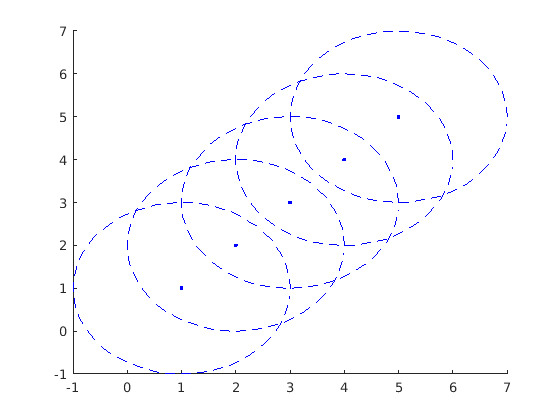

group = swarm(5, 2);
group.printDrones();

A = group.A

A =      0     1     0     0     0
     1     0     1     0     0
     0     1     0     1     0
     0     0     1     0     1
     0     0     0     1     0
